# Prep Neurosynth topic maps v4

**Purpose: **This script loads Neurosynth topic maps from .nii images into fmri_data objects (one for each of forward- and reverse-inference maps), loads a table of topic terms and number of studies, and attaches the term table in the **topic_obj.metadata_table **property.  It saves a mat file containing both fmri_data objects that can be loaded later and used in analyses.

The mat file is: **neurosynth_topics_v4.mat**

**Authors**: Tor Wager

**Date**: 1/2022

## Prep objects for Neurosynth topic analyses

Topic maps developed by Tal Yarkoni (Yarkoni 2014) are available from **Neurosynth.org**. A topic set containing 100 topics is in the CANlab Github **Neuroimaging_pattern_masks** repository. It includes the file "Neurosynth_Topics_v4-topics-100.csv", which is used to identify whether the topic folder is on the Matlab path.

"v4_topics" is a set of 100 topics extracted with LDA from the abstracts of all articles in the Neurosynth database as of July 2015 (11,406 articles). Some of these are related primarily to anatomical terms. A set of 42 interesting topic maps related to psychological terms was selected based on including mainly psychological content terms by Tor Wager.

**Forward and reverse inference maps**

In Neurosynth maps,  **pAgF** denotes probability of activation given topic ('forward inference'). **pFgA** denotes probability of topic given activation ('reverse inference'). Note that the 'reverse inference' maps do not guarantee specificity, as they reflect merely a greater probability that a map belongs to a topic than not given activation in significant voxels; this is determined with an association (chi-square) test not a multi-way classification test. Nonetheless, 'reverse inference' maps tend to be more spatially localized than 'forward inference' maps.

### Prep Reverse inference maps

topic_file = which('Neurosynth_Topics_v4-topics-100.csv');
which(topic_file) % error if not found - if error, add to path

/Users/f003vz1/Documents/GitHub/Neuroimaging_Pattern_Masks/Atlases_and_parcellations/2016_Neurosynth_100_topics/Neurosynth_Topics_v4-topics-100.csv



topic_path = fileparts(topic_file);

cd(topic_path)


**Load topic images and sort them in ascending order by topic number**


topic_name_wildcard = 'v4-topics-100_*pFgA_z_FDR_0.01.nii.gz';  % pFgA is probability of topic given activation ('reverse inference')

f = filenames(fullfile(topic_path, topic_name_wildcard)); 

% sort into numeric order
nums = regexp(f, 'v4-topics-100_\d+', 'match');
nums = [nums{:}];
nums = strrep(nums, 'v4-topics-100_', '');
nums = cellfun(@str2num, nums);
[nums_sorted, indx] = sort(nums);

f = f(indx);

topic_obj = fmri_data(f);

Using default mask: /Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 40816104 bytes
Loading image number:    42
Elapsed time is 0.357828 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 116351  Bit rate: 16.83 bits


**Load the topic file into a table, and match with images**

t = readtable(topic_file, "NumHeaderLines", 1);

t = t(:, 2:end);
t.Properties.VariableNames{1} = 'TopicNumber';
t.Properties.VariableNames{end} = 'Number_of_studies';

t(1:5, :)

ans = 5×42 table
    TopicNumber          Var3                 Var4                 Var5               Var6             Var7              Var8               Var9              Var10              Var11                Var12                Var13              Var14             Var15             Var16               Var17               Var18              Var19              Var20               Var21              Var22                Var23                     Var24                   Var25              Var26              Var27             Var28 


wh_rows = ismember(t.TopicNumber, nums_sorted);

t_excluded_topics = t(~wh_rows, :);

t = t(wh_rows, :);


**Exclude topics with <40 voxels**

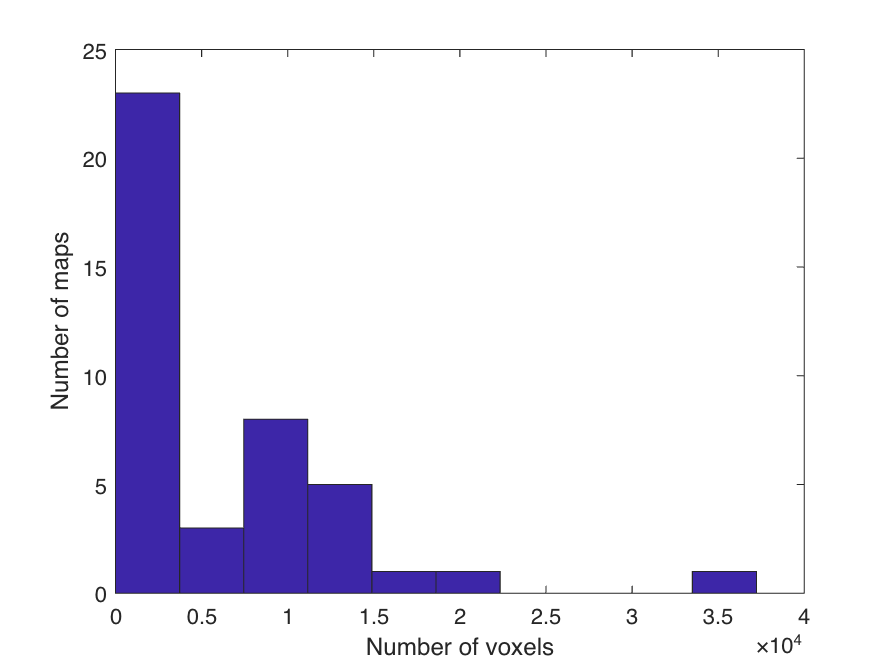

num_vox = sum(topic_obj.dat > 0);

wh_exclude = num_vox < 40;

figure; hist(num_vox);
ylabel('Number of maps')
xlabel('Number of voxels')


topic_obj = get_wh_image(topic_obj, ~wh_exclude);
t(wh_exclude, :) = [];

topic_obj.metadata_table = t;

disp('Excluded these topics:')

Excluded these topics:


find(wh_exclude)

ans =      7    14


**plot**

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |  40 images 


Retained 10 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 37.50%
Expected 2.00 outside 95% ellipsoid, found  11

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 4 images		Cases 24 32 37 40 
Uncorrected: 11 images		Cases 6 7 11 16 21 24 26 32 33 37 40 

Retained 16 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 37.50%
Expected 2.00 outside 95% ellipsoid, found   3

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 3 images		Cases 13 25 30 

Mahalanobis (cov and corr, q<0.05 corrected):
  4 images 
                               Outlier_count    Percentage
          

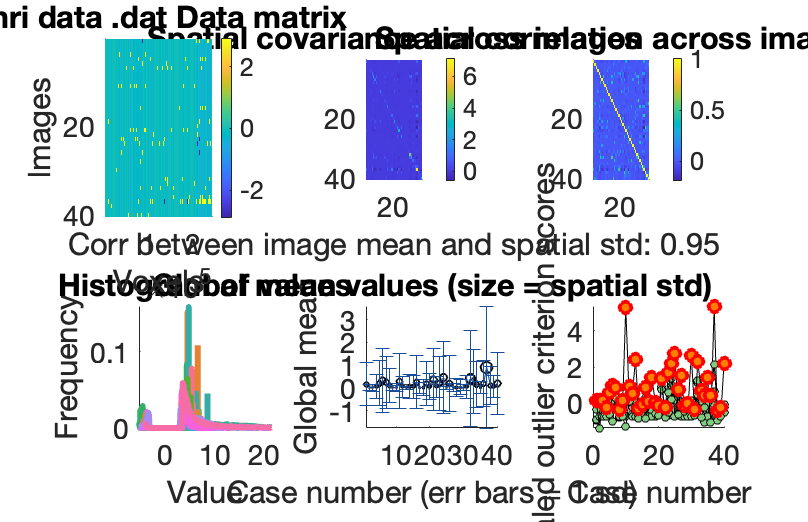

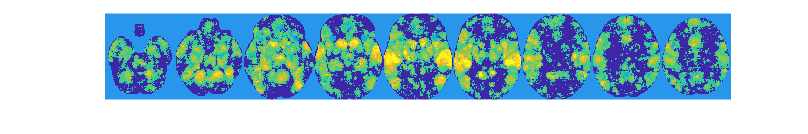

ans = 40×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


plot(topic_obj, 'noorthviews')

**Save **

topic_obj_reverseinference = topic_obj;

save neurosynth_topics_v4 topic_obj_reverseinference

### Prep Forward inference maps


topic_file = which('Neurosynth_Topics_v4-topics-100.csv');
which(topic_file) % error if not found - if error, add to path

/Users/f003vz1/Documents/GitHub/Neuroimaging_Pattern_Masks/Atlases_and_parcellations/2016_Neurosynth_100_topics/Neurosynth_Topics_v4-topics-100.csv



topic_path = fileparts(topic_file);

**Load topic images and sort them in ascending order by topic number**


topic_name_wildcard = 'v4-topics-100_*pAgF_z_FDR_0.01.nii.gz';  % pFgA is probability of topic given activation ('reverse inference')

f = filenames(fullfile(topic_path, topic_name_wildcard)); 

% sort into numeric order
nums = regexp(f, 'v4-topics-100_\d+', 'match');
nums = [nums{:}];
nums = strrep(nums, 'v4-topics-100_', '');
nums = cellfun(@str2num, nums);
[nums_sorted, indx] = sort(nums);

f = f(indx);

topic_obj = fmri_data(f);

Using default mask: /Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 40816104 bytes
Loading image number:    42
Elapsed time is 0.973785 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 2310  Bit rate: 11.17 bits


**Load the topic file into a table, and match with images**

t = readtable(topic_file, "NumHeaderLines", 1);

t = t(:, 2:end);
t.Properties.VariableNames{1} = 'TopicNumber';
t.Properties.VariableNames{end} = 'Number_of_studies';

t(1:5, :)

ans = 5×42 table
    TopicNumber          Var3                 Var4                 Var5               Var6             Var7              Var8               Var9              Var10              Var11                Var12                Var13              Var14             Var15             Var16               Var17               Var18              Var19              Var20               Var21              Var22                Var23                     Var24                   Var25              Var26              Var27             Var28 


wh_rows = ismember(t.TopicNumber, nums_sorted);

t_excluded_topics = t(~wh_rows, :);

t = t(wh_rows, :);


**Exclude topics with <40 voxels**

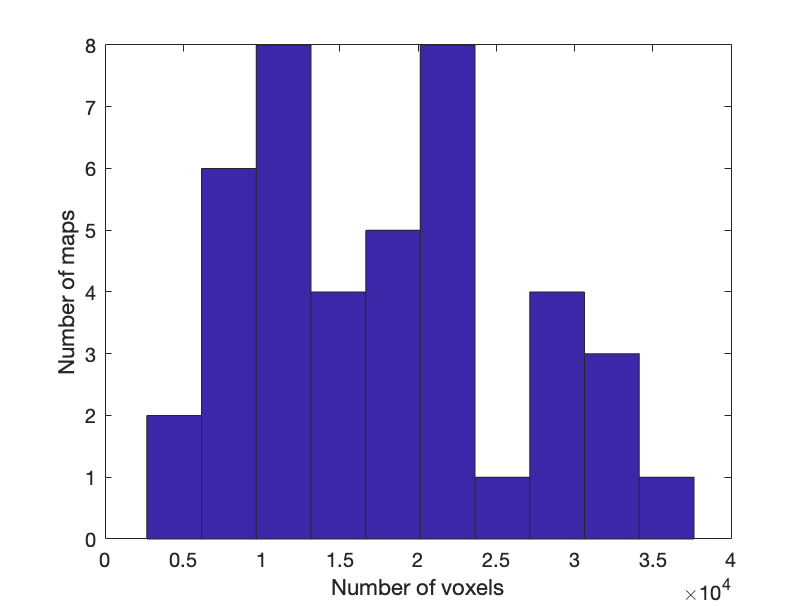

num_vox = sum(topic_obj.dat > 0);

wh_exclude = num_vox < 40;

figure; hist(num_vox);
ylabel('Number of maps')
xlabel('Number of voxels')


topic_obj = get_wh_image(topic_obj, ~wh_exclude);
t(wh_exclude, :) = [];

topic_obj.metadata_table = t;

disp('Excluded these topics:')

Excluded these topics:


find(wh_exclude)


ans =

  1×0 empty double row vector



**plot**

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |  42 images 


Retained 9 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 33.33%
Expected 2.10 outside 95% ellipsoid, found   7

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 3 images		Cases 34 39 42 
Uncorrected: 7 images		Cases 8 26 28 34 36 39 42 

Retained 9 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 45.24%
Expected 2.10 outside 95% ellipsoid, found   2

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 2 images		Cases 23 32 

Mahalanobis (cov and corr, q<0.05 corrected):
  3 images 
                               Outlier_count    Percentage
                              

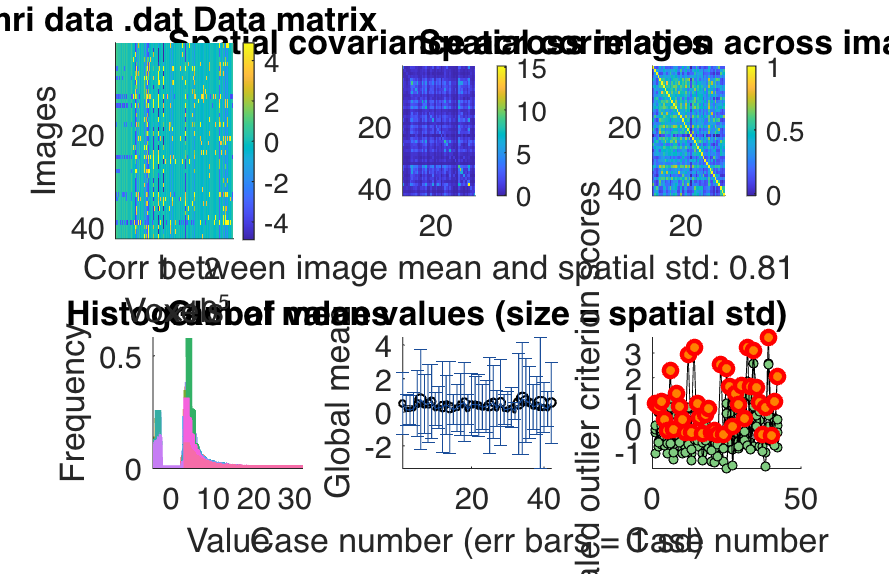

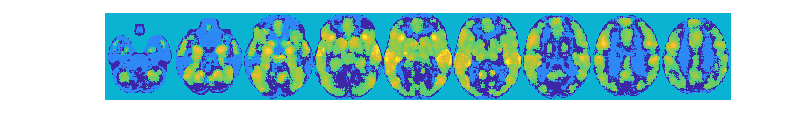

ans = 42×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


plot(topic_obj, 'noorthviews');

**Save **

topic_obj_forwardinference = topic_obj;

save neurosynth_topics_v4 -append topic_obj_forwardinference
